# **RS-MILP-02-01: Configure ADMM(Alternating Direction Method of Multipliers) for distributed approach of MILP**

**University of Texas at Austin**

**Department of Aerospace Engineering and Engineering Mechanics**

**Hongseok Kim**

## **1. Generate A matrix from contact chart**

clear;
clc;


addpath('/Library/gurobi1300/macos_universal2/matlab')
savepath

addpath ~/Desktop/Redstone_MILP/RS_MILP_01_Config_MILP/
load('EOIR_48_SATs_12_Orbit_Planes_98_inc_7days_access_interval.mat','EOIR_access_interval')


% 기준 시각 정의

T = EOIR_access_interval;

t0 = datetime(2030, 1, 1, 0, 0, 0,'TimeZone','UTC');

% --- Source / Target을 string으로 통일 ---
src = string(T.Source);
tgt = string(T.Target);

% --- Ground 번호 추출 ---
gTok = regexp(src, 'Ground[_\s]*Point[_\s]*(\d+)', 'tokens', 'once');
groundNum = cellfun(@(c) str2double(c{1}), gTok);

% --- Satellite 번호 추출 ---
sTok = regexp(tgt, '(?i)SAT[^0-9]*(\d+)', 'tokens', 'once');
satNum = cellfun(@(c) str2double(c{1}), sTok);

% --- Start / End → datetime ---
st = T.StartTime;
en = T.EndTime;

if ~isdatetime(st)
    st = datetime(string(st), 'InputFormat','dd-MMM-yyyy HH:mm:ss');
end
if ~isdatetime(en)
    en = datetime(string(en), 'InputFormat','dd-MMM-yyyy HH:mm:ss');
end

% --- 중간 시각 ---
midTime = st + (en - st)/2;

% --- 기준 시각 대비 초(second) 차이 → integer ---
timeSec = seconds(midTime - t0);
timeSec = double(round(timeSec));   % 정수화 (필요시 floor / ceil로 변경 가능)


contact_index = (1:length(st))';

% --- 최종 3-column matrix ---
A_matrix = [double(satNum), double(groundNum), timeSec, contact_index];

A_matrix = sortrows(A_matrix, 3);

A_matrix = A_matrix(1:500,:);
Original_A = T(A_matrix(:,4),:);


N = length(A_matrix(:,1));

## 2. Extract Key parameters from A matrix

t = A_matrix(:,3);

% Satellite Cadence Constraint
tau = 20;

% Number of SATs
p = 48;

% Number of GSs
q = 54;

% Total number of contact
N = length(A_matrix(:,1));

% Number of contact for each SAT
S_i_vec = zeros(p,1);

for sat_index = 1:p
    S_i_vec(sat_index) = nnz(A_matrix(:,1) == sat_index);
end

% Number of contact for each GS
G_j_vec = zeros(q,1);
for gs_index = 1:q
    G_j_vec(gs_index) = nnz(A_matrix(:,2) == gs_index);
end

## 3. Selection matrix generation from given constant parameters

### 3.1. $E_{S_i }^1$: Selection matrix from A-matrix to each satellite's contact sequence

E1_Si = struct();

for i = 1:p

E1_Si_mat = zeros(S_i_vec(i),N);

a_i = find(A_matrix(:,1) == i);

  for j = 1:length(a_i)
      E1_Si_mat(j, a_i(j)) = 1;
  end

  E1_Si.(['sat',num2str(i)]) = E1_Si_mat;

end

### 3.2. $E_{S_i ,x}^2 \;,E_{S_{i,t} }^2$: Selection matrix for $\Delta t$ of each satelltite from $\left|S_i \right|$

E2_Si_x = struct();

for i = 1:p
    E2_Si_x_mat = [];
    for alpha = 1:S_i_vec(i)-1
        E2_Si_x_alpha = zeros(S_i_vec(i)-alpha, S_i_vec(i));
        E2_Si_x_alpha(:,alpha) = 1;
        for beta = alpha+1:S_i_vec(i)
            E2_Si_x_alpha(beta-alpha,beta) = 1;
        end
     E2_Si_x_mat = [E2_Si_x_mat;E2_Si_x_alpha]; 
    end
   if isempty(E2_Si_x_mat)
     E2_Si_x_mat = 0;
   end
   E2_Si_x.(['sat',num2str(i)]) = E2_Si_x_mat;
end


E2_Si_t = struct();

for i = 1:p
    E2_Si_t_mat = [];
    for alpha = 1:S_i_vec(i)-1
        E2_Si_t_alpha = zeros(S_i_vec(i)-alpha, S_i_vec(i));
        E2_Si_t_alpha(:,alpha) = -1;
        for beta = alpha+1:S_i_vec(i)
            E2_Si_t_alpha(beta-alpha,beta) = 1;
        end
     E2_Si_t_mat = [E2_Si_t_mat;E2_Si_t_alpha]; 
    end
   if isempty(E2_Si_t_mat)
     E2_Si_t_mat = 0;
   end
    E2_Si_t.(['sat',num2str(i)]) = E2_Si_t_mat;
end

### 3.3. $E_{G_j }^1$: Selection matrix from A-matrix to each Ground Point's revisit sequence

E1_Gj = struct();

for j = 1:q
    E1_Gj_mat = zeros(G_j_vec(j)+2, N+2);

    E1_Gj_mat(1,1) = 1;
    b_j = find(A_matrix(:,2) == j);

    for alpha = 1:length(b_j)
        E1_Gj_mat(alpha+1, b_j(alpha)+1) = 1;
    end
    E1_Gj_mat(G_j_vec(j)+2, N+2) = 1;
    E1_Gj.(['gs', num2str(j)]) = E1_Gj_mat;
end

### 3.4. $E_{G_{j,x} }^2 \;,E_{G_{j,t} }^2$: Selection matrix for $\Delta t$ of each GS from $\left|G_j \right|$

E2_Gj_x = struct();

for j = 1:q
    E2_Gj_x_mat = [];
    for alpha = 1:G_j_vec(j)+1
        E2_Gj_x_alpha = zeros(G_j_vec(j)+2-alpha, G_j_vec(j)+2);
        E2_Gj_x_alpha(:,alpha) = 1;
        for beta = alpha+1:G_j_vec(j)+2
            if alpha + 1 <= beta-1
               E2_Gj_x_alpha(beta-alpha, alpha+1:beta-1) = -1; 
            end
            E2_Gj_x_alpha(beta-alpha,beta) = 1;
        end
     E2_Gj_x_mat = [E2_Gj_x_mat;E2_Gj_x_alpha]; 
    end
   if isempty(E2_Gj_x_mat)
     E2_Gj_x_mat = 0;
   end
   E2_Gj_x.(['gs',num2str(j)]) = E2_Gj_x_mat;
end

E2_Gj_t = struct();

for j = 1:q
    E2_Gj_t_mat = [];
    for alpha = 1:G_j_vec(j)+1
        E2_Gj_t_alpha = zeros(G_j_vec(j)+2-alpha, G_j_vec(j)+2);
        E2_Gj_t_alpha(:,alpha) = -1;
        for beta = alpha+1:G_j_vec(j)+2
            E2_Gj_t_alpha(beta-alpha,beta) = 1;
        end
     E2_Gj_t_mat = [E2_Gj_t_mat;E2_Gj_t_alpha]; 
    end
   if isempty(E2_Gj_t_mat)
     E2_Gj_t_mat = 0;
   end
   E2_Gj_t.(['gs',num2str(j)]) = E2_Gj_t_mat;
end

### 4. Derivation of $A,b,C,d,E,f,G$ revisit time problem to MILP

#### 4.1 $A,b$ for $L_1$ problem , $A_{s_i }$, $b_{s_i }$ for BCD/ADMM , $P-\textrm{matrix}$ for Permutation, $U,V$ for sizing index

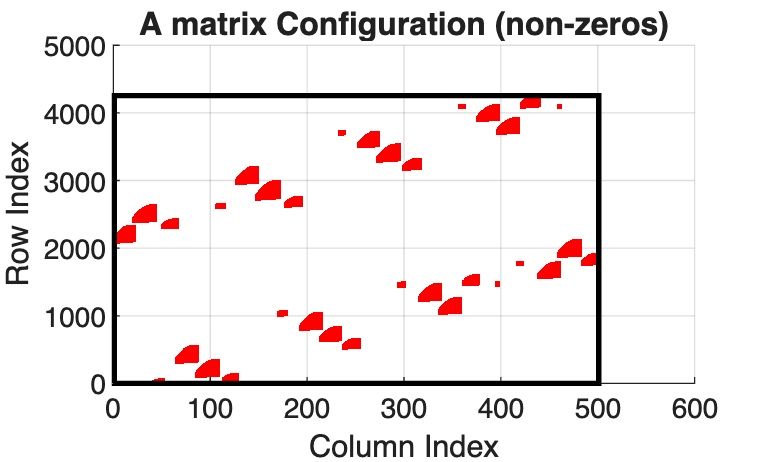

A = [];
b_mat = [];
P_matrix_transpose = [];

U = 0;
V = 0;

for i = 1:p
  if isempty(E1_Si.(['sat', num2str(i)])) 
  continue;
  end

  A_i = E2_Si_x.(['sat', num2str(i)]) * E1_Si.(['sat', num2str(i)]);
  A = [A;A_i];
  b_i_mat =  E2_Si_t.(['sat', num2str(i)]) * E1_Si.(['sat', num2str(i)]);
  b_mat = [b_mat; b_i_mat];


  A_si_info.(['sat', num2str(i)]) = E2_Si_x.(['sat', num2str(i)]);
  b_si_info.(['sat', num2str(i)]) = ones(length(b_i_mat(:,1)),1) + 1/tau * b_i_mat* A_matrix(:,3);

  P_matrix_transpose = [P_matrix_transpose; E1_Si.(['sat', num2str(i)])];

  E1_si = E1_Si.(['sat', num2str(i)]);
  S_i_info.(['sat', num2str(i)]) = length(E1_si(:,1));

  U_i_info.(['sat', num2str(i)]) = U;
  V_i_info.(['sat', num2str(i)]) = N - length(E1_si(:,1)) - U;
  U = U + length(E1_si(:,1));

end



b = ones(length(b_mat(:,1)),1) + 1/tau * b_mat * A_matrix(:,3);
P_matrix = P_matrix_transpose';


[A_row, A_col] = find(A==1);
figure;
hold on
scatter(A_col,A_row,'r','.')
rectangle('Position',[1 1 max(A_col), max(A_row)], ...
          'EdgeColor','k', ...
          'LineWidth',2);
title('A matrix Configuration (non-zeros)','FontSize',12,'FontWeight','bold')
xlabel('Column Index')
ylabel('Row Index')
grid on

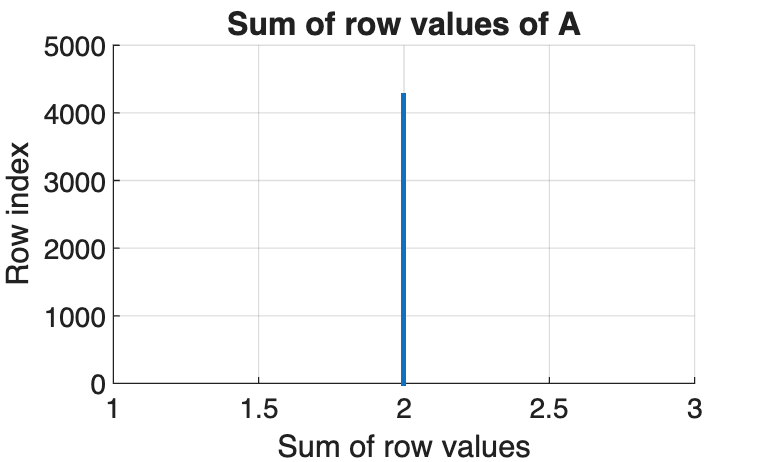



row_sum = sum(A, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_sum,1:length(row_sum),'.');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of row values')
title('Sum of row values of A','FontSize',12,'FontWeight','bold')

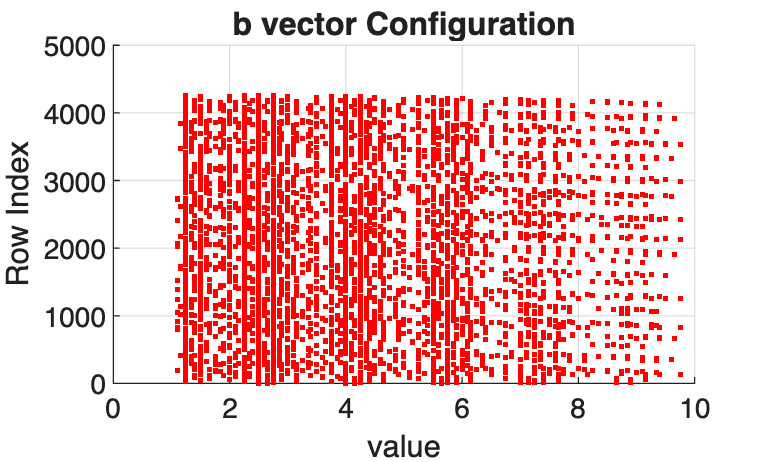



figure;
scatter(b,1:length(b),'r','.')
title('b vector Configuration','FontSize',12,'FontWeight','bold')
xlabel('value')
ylabel('Row Index')
xlim([0,10])
grid on

#### 4.2 $C,d$ for $L_{\infty }$ problem

C = [];
d = [];

t = A_matrix(:,3);                  % (N×1) time vector in seconds (already prepared)
t_aug = [min(A_matrix(:,3)); t; max(A_matrix(:,3))+1];        % (N+2 × 1)

for j = 1:q
    key = ['gs', num2str(j)];

    if isempty(E1_Gj.(key))
        continue;
    end

    % --- shorthand ---
    E1  = E1_Gj.(key);        % selection matrix for this ground
    E2x = E2_Gj_x.(key);
    E2t = E2_Gj_t.(key);

    % =========================
    % Build C_j  (constant)
    % =========================
    % D_j = diag( E2t*E1 * t_aug )   (vector -> diagonal matrix)
    Dj_vec = (E2t * E1) * t_aug;           % (#rows_j × 1)
    Dj = spdiags(Dj_vec, 0, length(Dj_vec), length(Dj_vec));  % sparse diag is safer

    % P = [0_{1×N}; I_{N×N}; 0_{1×N}]  -> (N+2 × N)
    N = length(t);
    P = [zeros(1,N); speye(N); zeros(1,N)];

    % C_j = D_j * (E2x*E1) * P
    Cj = Dj * (E2x * E1) * P;

    % =========================
    % Build d_j  (constant)
    % =========================
    % v = [1; 0_{N×1}; 1] - 1  = [0; -1...; 0]
    v = [1; zeros(N,1); 1];          % (N+2 × 1)

    % d_j = D_j * (E2x*E1) * v
    dj = Dj * ((E2x * E1) * v - ones(length(Dj(:,1)),1));

    % --- stack ---
    C = [C; Cj];
    d = [d; dj];
end


% [C_row, C_col] = find(C~=0);
% 
% figure;
% scatter(C_row, C_col,'r','.')
% grid on

#### 4.3 $E,f,G$ for $L_2$ Optimization problem

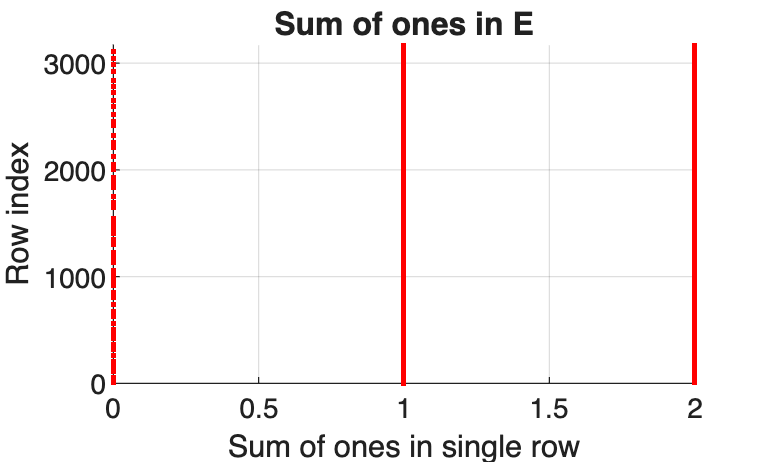

% =========================
% Build E, f, G  (2nd image)
% =========================

E_ori = [];
F = [];

t = A_matrix(:,3);                       % (N×1)
N = length(t);

t_aug = [min(t); t; max(t)+1];                % (N+2 × 1), same as your code

% P = [0_{1×N}; I_N; 0_{1×N}]  -> (N+2 × N)
P = [zeros(1,N); speye(N); zeros(1,N)];

% this is the (N+2 × 1) vector [1; 0_N; 1]
one_aug = [1; zeros(N,1); 1];

% For G, we will build the stacked matrix Bt = [E2t*E1; ...] first (optional),
% or directly build gvec = Bt*t_aug.
gvec = [];   % = Bt * t_aug  (will be stacked across j)

for j = 1:q
    key = ['gs', num2str(j)];

    if isempty(E1_Gj.(key))
        continue;
    end

    % --- shorthand ---
    E1  = E1_Gj.(key);        % selection matrix for this ground
    E2x = E2_Gj_x.(key);
    E2t = E2_Gj_t.(key);

    % Common blocks
    Sx = (E2x * E1);          % (#rows_j × (N+2))
    St = (E2t * E1);          % (#rows_j × (N+2))

    % -------------------------
    % E_j = Sx * P    (constant)
    % -------------------------
    Ej = Sx;              % (#rows_j × N)
    E_ori  = [E_ori; Ej];

    % -------------------------
    % f_j = Sx]
    % -------------------------
    Fj = Sx;        % (#rows_j × 1)
    F  = [F; Fj];

    % -------------------------
    % gvec_j = St * t_aug
    % -------------------------
    gvec_j = St * t_aug;      % (#rows_j × 1)
    gvec   = [gvec; gvec_j];
end

% Dj = spdiags(Dj_vec, 0, length(Dj_vec), length(Dj_vec)); 

E = E_ori * P;
f_vector = F * one_aug;

% -------------------------
% G = gvec * gvec'
% -------------------------
% WARNING: this can be very large/dense if gvec is long.
% If you only need y'*G*y, note that y'*(gvec*gvec')*y = (gvec'*y)^2.
G = spdiags(gvec, 0, length(gvec), length(gvec));   % (M×M)


[E_one_col, E_one_row] = find(E == 1);
[E_minus_one_col, E_minus_one_row] = find(E == -1);

figure;
hold on
scatter(E_minus_one_row, E_minus_one_col,'blue','.')
scatter(E_one_row, E_one_col,'red','.')


grid on
title('E matrix Configuration (non-zeros)','FontSize',12,'FontWeight','bold')
xlabel('Column Index')
ylabel('Row Index')
grid on
row_sum = sum(E, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_sum,1:length(row_sum),'.');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of row values')
title('Sum of row values of E','FontSize',12,'FontWeight','bold')


row_one_sum = sum(E == 1, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_one_sum,1:length(row_one_sum),'.','r');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of ones in single row')
title('Sum of ones in E','FontSize',12,'FontWeight','bold')

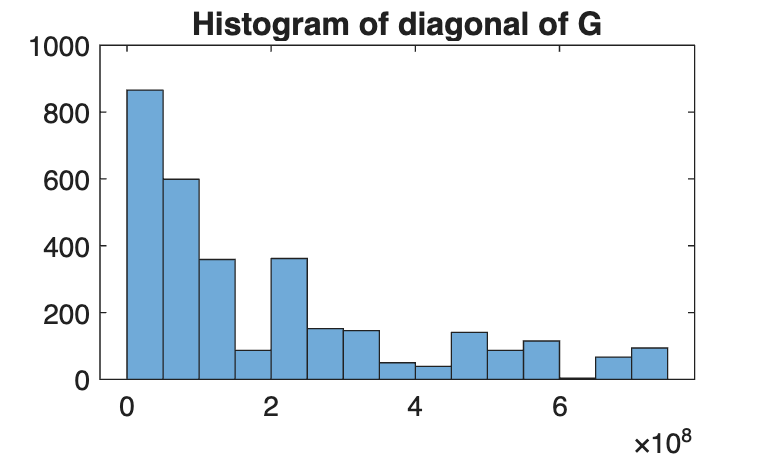


scatter(1:length(gvec),gvec.^2,'r','.')
title('Value of diagonal of G','FontSize',12,'FontWeight','bold');
ylabel('value')
xlabel('Diagonal Index')
grid on

figure;
histogram(gvec.^2)
title('Histogram of diagonal of G','FontSize',12,'FontWeight','bold');


scatter(f_vector,1:length(f_vector),'r','.')
title('f vector Configuration','FontSize',12,'FontWeight','bold')
xlabel('value')
ylabel('Row Index')
grid on

## 5. Solving MILP by ADMM

### 5.1 ADMM

%% =========================
%  Consensus ADMM for (MIQP/MILP-like) with z >= E*P*xbar + f - 1
%   - each agent i updates (x_{s_i}, z_{s_i}) in parallel/serial
%   - global z enforces consensus: z_{s_i} = z
%   - dual variables lambda_i (same dimension as z)
%% =========================

% ---- user provided initializations (keep) ----
x = zeros(length(A_matrix(:,1)),1);     % global x (binary)
z = zeros(length(f_vector),1);          % global consensus z (continuous)

% ---- ADMM options ----
maxIters   = 200;
rho        = 0;       % penalty parameter
tol_primal = 1e-4;      % ||r|| tolerance
tol_dual   = 1e-4;      % ||s|| tolerance
verbose    = 1;

% ---- precompute constant matrices ----
EP = E * P_matrix;      % used for z lower bound

% ---- build block index map (idx_i for each agent) ----
idx_block = cell(p,1);
for i = 1:p
    if isempty(E1_Si.(['sat', num2str(i)]))
        idx_block{i} = [];
        continue;
    end
    U = U_i_info.(['sat', num2str(i)]);
    S_i = S_i_info.(['sat', num2str(i)]);
    nSi = length(S_i);
    idx_block{i} = (U+1):(U+nSi);
end

% ---- dual variables (one lambda per agent, dimension = length(z)) ----
m = length(f_vector);
lambda = cell(p,1);
for i = 1:p
    lambda{i} = zeros(m,1);
end

% ---- histories (optional) ----
x_hist = [];
z_hist = [];
r_hist = [];
s_hist = [];

% ---- weight for quadratic on z_{s_i} ----
g = (gvec(:)).^2;   % objective uses z' diag(g) z

% ---- main ADMM loop ----
z_prev = z;

for k = 1:maxIters

    % snapshot
    x_k = x;
    z_k = z;

    % stacked xbar = P' x
    xbar_k = P_matrix' * x_k;

    % store local solutions
    z_si_all = cell(p,1);
    xbar_new_all = cell(p,1);

    % ========= (1) Local updates: for each agent i, solve MIQP in (x_si, z_si)
    for i = 1:p
        if isempty(E1_Si.(['sat', num2str(i)]))
            z_si_all{i} = z_k;          % dummy
            xbar_new_all{i} = xbar_k;   % dummy
            continue;
        end

        % local constraints
        A_si = A_si_info.(['sat', num2str(i)]);
        b_si = b_si_info.(['sat', num2str(i)]);

        % current local block (from global x)
        x_si_k = E1_Si.(['sat', num2str(i)]) * x_k;

        % coupling base term: base0 = EP*xbar_k + f - 1
        base0 = EP * xbar_k + f_vector - 1;

        % EP_i: columns corresponding to agent i block inside xbar
        U  = U_i_info.(['sat', num2str(i)]);
        S  = S_i_info.(['sat', num2str(i)]);
        EP_i = EP(:, (U+1):(U+S));   % m x |S_i|

        % solve local MIQP:
        %   min  z_si' diag(g) z_si + lambda_i' (z_si - z_k) + (rho/2)||z_si - z_k||^2
        %   s.t. A_si x_si <= b_si, x_si binary
        %        z_si >= base0 + EP_i*(x_si - x_si_k)
        %        z_si >= 0
        params = struct();
        params.OutputFlag = 0;

        sol = solve_local_admm_milp_gurobi(A_si, b_si, EP_i, base0, x_si_k, ...
                                           g, z_k, lambda{i}, rho, params);

        if ~sol.success
            if verbose
                fprintf('[ADMM] iter=%d sat%d local solve failed (status=%s). Keep.\n', k, i, sol.status);
            end
            z_si_all{i} = z_k;
            xbar_new_all{i} = xbar_k;
            continue;
        end

        x_si_new = sol.x_si;
        z_si_new = sol.z_si;

        % write back agent-updated xbar (only for agent i block)
        % xbar_new = xbar_k + J_i*(x_si_new - x_si_k)
        J_i = sparse(length(xbar_k), length(x_si_k));
        J_i(U+1:U+S, :) = speye(S);

        xbar_new = xbar_k + J_i * (x_si_new - x_si_k);

        z_si_all{i} = z_si_new;
        xbar_new_all{i} = xbar_new;
    end

    % ========= (2) Global x update
    % 보통 consensus ADMM에서는 x를 "각 agent의 x_si를 합쳐" 업데이트해야 합니다.
    % 여기서는 가장 단순히 "마지막 sweep의 xbar_new_all{i}"를 사용하거나,
    % 혹은 다수결/평균 후 rounding 등을 설계할 수 있습니다.
    %
    % 아래는 "sequential sweep"처럼 i=1..p 순서로 반영한 결과를 사용:
    xbar_seq = xbar_k;
    for i = 1:p
        if isempty(idx_block{i}), continue; end
        U  = U_i_info.(['sat', num2str(i)]);
        S  = S_i_info.(['sat', num2str(i)]);
        xbar_seq(U+1:U+S) = xbar_new_all{i}(U+1:U+S);
    end
    x = P_matrix * xbar_seq;

    % ========= (3) Global z update (Option i): element-wise max of local z_si
    m = length(f_vector);
    z_new = -inf(m,1);
    
    cnt = 0;
    for i = 1:p
        if isempty(E1_Si.(['sat', num2str(i)])), continue; end
        z_new = max(z_new, z_si_all{i});   % element-wise max
        cnt = cnt + 1;
    end
    
    if cnt == 0
        z_new = z_k;
    end
    
    % (강력 권장) 전역 coupling 하한도 같이 만족시키기: z >= EP*xbar + f - 1, z>=0
    xbar = P_matrix' * x;                 % x는 (2) x-update 이후의 최신 값
    lb1  = EP * xbar + f_vector - 1;
    lb2  = zeros(m,1);
    z    = max(z_new, max(lb1, lb2));


    % ========= (4) Dual update
    for i = 1:p
        if isempty(E1_Si.(['sat', num2str(i)])), continue; end
        lambda{i} = lambda{i} + rho*( z_si_all{i} - z );
    end

    % ========= (5) Residual checks
    % primal residual: r_i = z_si - z
    r_norm = 0;
    cnt = 0;
    for i = 1:p
        if isempty(E1_Si.(['sat', num2str(i)])), continue; end
        r_norm = r_norm + norm(z_si_all{i} - z, 2)^2;
        cnt = cnt + 1;
    end
    r_norm = sqrt(r_norm);

    % dual residual: s = rho*(z - z_prev)
    s_norm = rho * norm(z - z_prev, 2);

    % histories
    x_hist = [x_hist, x];
    z_hist = [z_hist, z];
    r_hist = [r_hist, r_norm];
    s_hist = [s_hist, s_norm];

    if verbose
        fprintf('[ADMM] iter=%3d |r|=%.3e |s|=%.3e\n', k, r_norm, s_norm);
    end

    if (r_norm <= tol_primal) && (s_norm <= tol_dual)
        if verbose, fprintf('[ADMM] Converged at iter=%d\n', k); end
        break;
    end

    z_prev = z;
end

[ADMM] iter=  1 |r|=1.266e+02 |s|=0.000e+00
[ADMM] iter=  2 |r|=1.216e+02 |s|=0.000e+00
[ADMM] iter=  3 |r|=1.277e+02 |s|=0.000e+00
[ADMM] iter=  4 |r|=1.281e+02 |s|=0.000e+00
[ADMM] iter=  5 |r|=1.305e+02 |s|=0.000e+00
[ADMM] iter=  6 |r|=1.313e+02 |s|=0.000e+00
[ADMM] iter=  7 |r|=1.324e+02 |s|=0.000e+00
[ADMM] iter=  8 |r|=1.340e+02 |s|=0.000e+00
[ADMM] iter=  9 |r|=1.337e+02 |s|=0.000e+00
[ADMM] iter= 10 |r|=1.344e+02 |s|=0.000e+00
[ADMM] iter= 11 |r|=1.337e+02 |s|=0.000e+00
[ADMM] iter= 12 |r|=1.344e+02 |s|=0.000e+00
[ADMM] iter= 13 |r|=1.337e+02 |s|=0.000e+00
[ADMM] iter= 14 |r|=1.344e+02 |s|=0.000e+00
[ADMM] iter= 15 |r|=1.337e+02 |s|=0.000e+00
[ADMM] iter= 16 |r|=1.344e+02 |s|=0.000e+00
[ADMM] iter= 17 |r|=1.337e+02 |s|=0.000e+00
[ADMM] iter= 18 |r|=1.344e+02 |s|=0.000e+00
[ADMM] iter= 19 |r|=1.337e+02 |s|=0.000e+00
[ADMM] iter= 20 |r|=1.344e+02 |s|=0.000e+00
[ADMM] iter= 21 |r|=1.337e+02 |s|=0.000e+00
[ADMM] iter= 22 |r|=1.344e+02 |s|=0.000e+00
[ADMM] iter= 23 |r|=1.337e+02 |s


Interrupt request received

Interrupt request received


[ADMM] iter=98 sat12 local solve failed (status=INTERRUPTED). Keep.


[ADMM] iter= 98 |r|=1.619e+02 |s|=0.000e+00
[ADMM] iter= 99 |r|=1.313e+02 |s|=0.000e+00
[ADMM] iter=100 |r|=1.329e+02 |s|=0.000e+00
[ADMM] iter=101 |r|=1.342e+02 |s|=0.000e+00
[ADMM] iter=102 |r|=1.334e+02 |s|=0.000e+00
[ADMM] iter=103 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=104 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=105 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=106 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=107 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=108 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=109 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=110 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=111 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=112 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=113 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=114 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=115 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=116 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=117 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=118 |r|=1.339e+02 |s|=0.000e+00
[ADMM] iter=119 |r|=1.341e+02 |s|=0.000e+00
[ADMM] iter=120 |r|=1.339e+02 |s

function sol = solve_local_admm_milp_gurobi(A_si, b_si, EP_i, base0, x_si_k, ...
                                                    gvec, z_k, lambda_i, rho, params)
% Solve local MIQP:
%
%   min_{x_si in {0,1}^n, z in R^m}
%       g' z + lambda' (z - z_k) + (rho/2) ||z - z_k||_2^2
%   s.t.
%       A_si x_si <= b_si
%       z >= base0 + EP_i*(x_si - x_si_k)
%       z >= 0
%
% Variables v = [x; z].

    if nargin < 10 || isempty(params), params = struct(); end
    if ~isfield(params,'OutputFlag'),   params.OutputFlag = 0; end
    if ~isfield(params,'LogToConsole'), params.LogToConsole = 0; end
    if ~isfield(params,'LogFile'),      params.LogFile = ''; end

    gvec     = gvec(:);
    z_k      = z_k(:);
    lambda_i = lambda_i(:);

    n = size(A_si,2);      % |x_si|
    m = length(base0);     % |z|

    % -------------------------
    % Objective expansion:
    % g'z + lambda'(z - z_k) + (rho/2)||z - z_k||^2
    %
    % = (rho/2) z'z + (g + lambda - rho z_k)' z + const
    %
    % Gurobi form: min (1/2) v'Qv + c'v
    % -> put Qzz = rho*I  (because (1/2) z'(rho I) z = (rho/2) z'z)
    % -> linear term on z: c_z = g + lambda - rho z_k
    % -------------------------
    Q = sparse(n+m, n+m);
    Q(n+1:n+m, n+1:n+m) = rho * speye(m);

    c = zeros(n+m,1);
    c(n+1:n+m) = gvec + lambda_i - rho*z_k;

    % -------------------------
    % Constraints:
    % (1) A_si x <= b_si
    % (2) z >= base0 + EP_i*(x - x_k)
    %     -> -z + EP_i*x <= -(base0 - EP_i*x_k)
    % (3) z >= 0 handled by lb on z
    % -------------------------
    A1   = [A_si, sparse(size(A_si,1), m)];
    rhs1 = b_si;

    A2   = [EP_i, -speye(m)];
    rhs2 = -(base0 - EP_i*x_si_k);

    A    = sparse([A1; A2]);
    rhs  = [rhs1; rhs2];
    sense = repmat('<', size(A,1), 1);

    % bounds
    lb = -inf(n+m,1);
    ub =  inf(n+m,1);

    lb(1:n) = 0;   ub(1:n) = 1;     % x binary bounds
    lb(n+1:n+m) = 0;                % z >= 0

    vtype = repmat('C', n+m, 1);
    vtype(1:n) = 'B';

    model.Q = Q;
    model.obj = c;
    model.A = A;
    model.rhs = rhs;
    model.sense = sense;
    model.lb = lb;
    model.ub = ub;
    model.vtype = vtype;
    model.modelsense = 'min';

    % Solve
    try
        result = gurobi(model, params);
    catch ME
        sol.success = false;
        sol.status  = ['error: ' ME.message];
        sol.x_si = [];
        sol.z_si = [];
        return;
    end

    sol.status = result.status;

    if isfield(result,'x') && strcmpi(result.status,'OPTIMAL')
        v = result.x;
        sol.x_si = v(1:n);
        sol.z_si = v(n+1:n+m);
        sol.success = true;
    else
        sol.success = false;
        sol.x_si = [];
        sol.z_si = [];
    end
end
